# Lab - Initial value problems 4

**Topics: **Implicit & Explicit Euler

## Pendulum problem


$$\frac{d^2 \theta }{{\textrm{dt}}^2 }+\frac{g}{L}\theta =0$$


Compute the period for a 1-meter pendulum with the initial conditions $\theta =\frac{\pi }{8}\;\textrm{and}\;\frac{d\theta }{\textrm{dt}}=0$

g = 9.81;
L = 1;
theta0 = pi/8;
omega0 = 0;
Y0 = [theta0 omega0]';

### Analytical solution

syms theta(t)
Dtheta = diff(theta);
ode = diff(theta, t, 2) + g/L*theta == 0;

cond1 = theta(0) == pi/8;
cond2 = Dtheta(0) == 0;
conds = [cond1 cond2];

solution(t) = dsolve(ode, conds)

$$solution(t) = \frac{\pi \,\cos\left(\frac{3\,\sqrt{109}\,t}{10}\right)}{8}$$

### Solve using ode45

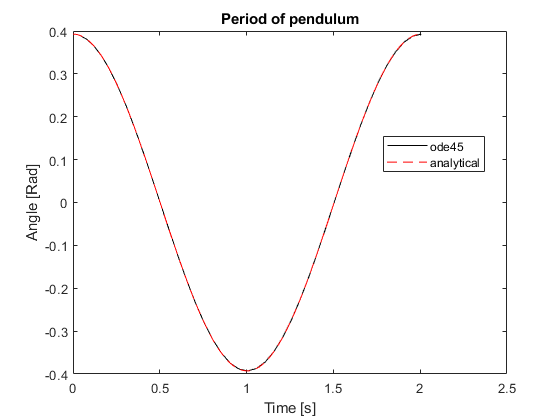

opts = odeset("events", @endevent);
[t y] = ode45(@swingingPendulum, [0,inf], Y0, opts, L);
tf = 4*t(end);
[t, Y_ODE] = ode45(@swingingPendulum, [0,tf], Y0, [], L);
plot(t,Y_ODE(:,1), "k")
hold on
fplot(solution, [0 tf], "r--")
title("Period of pendulum")
xlabel("Time [s]")
ylabel("Angle [Rad]")
legend("ode45", "analytical", "location", "best")
hold off

### Solve using explicit Euler

$\begin{array}{l}
Y_{i+1} =\left(I+\textrm{Ah}\right)Y_i \\
A=\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{g}{L} & 0
\end{array}\right\rbrack 
\end{array}$h= 0.1, 1st five values

h = 0.1;
A = [0 1;
     -g/L 0];
M = eye(2) + A*h;

Y1 = M*Y0;
Y2 = M*Y1;
Y3 = M*Y2;
Y4 = M*Y3;
Y5 = M*Y4;

Y = [Y0 Y1 Y2 Y3 Y4 Y5]';
theta_explicit = Y(:,1);
t_explicit = 0:h:5*h;

### Solve using implicit Euler


$$Y_{i+1} ={\left(I-Ah\right)}^{-1} Y_i$$


M = inv(eye(2) - A*h);

M =     0.9107    0.0911
   -0.8934    0.9107



Y1 = M*Y0;
Y2 = M*Y1;
Y3 = M*Y2;
Y4 = M*Y3;
Y5 = M*Y4;

Y = [Y0 Y1 Y2 Y3 Y4 Y5]';
theta_implicit = Y(:,1);
t_implicit = 0:h:5*h;

### Plotting

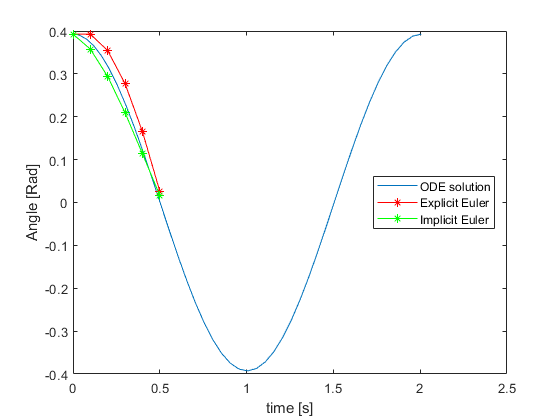

figure()
plot(t,Y_ODE(:,1))
hold on
plot(t_explicit, theta_explicit, "-r*")
plot(t_implicit, theta_implicit, "-g*")
legend("ODE solution", "Explicit Euler", "Implicit Euler", "location", "best")
xlabel("time [s]")
ylabel("Angle [Rad]")
hold off

## HELPER FUNCTIONS

### Function modeling swinging pendulum


$$\frac{d}{\textrm{dt}}\left\lbrack Y\right\rbrack =\left\lbrack \begin{array}{c}
Y\left(2\right)\\
-\frac{g}{L}Y\left(1\right)
\end{array}\right\rbrack$$


function dY = swingingPendulum(t,Y,L)
g = 9.81;
dY = [Y(2)
     -g/L*Y(1)];
end

### Event function to end integration

$Y=\left\lbrack \begin{array}{c}
\theta \\
\omega 
\end{array}\right\rbrack$find when $\theta =0$

function [detect, stopint, direction] = ...
    endevent(t,y, varargin)
detect = y(1);
stopint = 1; % Stop the integration
direction = 0;  % 0  direction doesn't matter
end